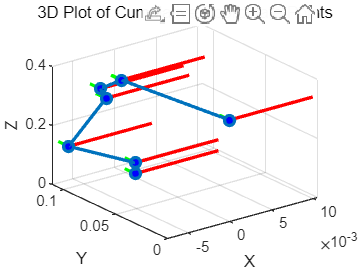

% 定义坐标点
coords = [
    -0.00110,  0.095,   -0.013327;   % left_hip_pitch
     -0.00185,  0.0055,   -0.024;    % left_hip_roll
     0,        -0.0055,  -0.02315;   % left_hip_yaw
    -0.0045,   0.0000,  -0.128;      % left_knee_jo
     0.008,     0,        -0.118;    % left_foot_y_jo
     0,         0  ,  -0.037;        % left_foot_x_jo


    -0.00110, -0.095,   -0.013327;   % right_hip_pitch 
    -0.00185,  -0.0055,   -0.024;    % right_hip_roll
     0         ,0.0055,  -0.02315;   % right_hip_yaw
    -0.0045,   0.0000,  -0.128;      % right_knee_jo
     0.008,     0,        -0.118;    % right_foot_y_jo
     0,         0,    -0.037;        % right_foot_x_jo
];

% 定义六个相对坐标点
relative_coords = [

     0 ,0,0.343477;
    % -0.00110,  0.095,   -0.013327; % left_hip_pitch
    %  0.00185,  0.0055,  -0.024;    % left_hip_roll
    %  0,       -0.0055, -0.02315;  % left_hip_yaw
    % -0.0045,  -0.0000, -0.128;    % left_knee_jo
    %  0.008,    0,       -0.118;    % left_foot_y_jo
    %  0,        0.001,   -0.037;    % left_foot_x_jo

    -0.00110,  0.095,   -0.013327; % left_hip_pitch
     -0.00185,  0.0055,   -0.024;    % left_hip_roll
     0,        -0.0055,  -0.02315;  % left_hip_yaw
    -0.0045,   0.0000,  -0.128;    % left_knee_jo
     0.008,     0,        -0.118;    % left_foot_y_jo
     0,         0  ,  -0.037;   % left_foot_x_jo



    % 
    %  0.00110, -0.095,   -0.013327; % right_hip_pitch 
    % -0.00185,  -0.0055,   -0.024;    % right_hip_roll
    %  0         ,0.00525,  -0.02315;  % right_hip_yaw
    % -0.0045,   -0.00025,  -0.128;    % right_knee_jo
    %  0.008,     0,        -0.118;    % right_foot_y_jo
    %  0,         0.001,    -0.037;    % right_foot_x_j
    % 

];

% 初始化绝对坐标数组
absolute_coords = zeros(size(relative_coords));

% 第一个点的绝对坐标与相对坐标相同
absolute_coords(1, :) = relative_coords(1, :);

% 计算后续点的绝对坐标
for i = 2:size(relative_coords, 1)
    absolute_coords(i, :) = absolute_coords(i-1, :) + relative_coords(i, :);
end

% 提取X、Y、Z坐标
x = absolute_coords(:,1);
y = absolute_coords(:,2);
z = absolute_coords(:,3);

% 绘制3D散点图并连接线段
figure (1);
plot3(x, y, z, '-o', 'MarkerFaceColor', 'blue', 'LineWidth', 2);
title('3D Plot of Cumulative Coordinate Points');
xlabel('X');
ylabel('Y');
zlabel('Z');
grid on;
hold on;

%为每个点绘制局部坐标系
scale = 0.01; % 坐标系轴的长度
for i = 1:length(x)
    % 绘制X轴
    plot3([x(i), x(i) + scale], [y(i), y(i)], [z(i), z(i)], 'r', 'LineWidth', 2);
    % 绘制Y轴
    plot3([x(i), x(i)], [y(i), y(i) + scale], [z(i), z(i)], 'g', 'LineWidth', 2);
    % 绘制Z轴
    plot3([x(i), x(i)], [y(i), y(i)], [z(i), z(i) + scale], 'b', 'LineWidth', 2);
end
hold on

% % 添加点的标签
% joint_names = {'base_pose','left\_hip\_pitch', 'left\_hip\_roll', 'left\_hip\_yaw', ...
%                'left\_knee\_jo', 'left\_foot\_y\_jo', 'left\_foot\_x\_jo'};
% 
% % 循环添加文本标签
% for i = 1:length(joint_names)
%     text(x(i), y(i), z(i), joint_names{i}, 'VerticalAlignment','bottom','HorizontalAlignment','right');
% end



% 
% l1=((-0.00110-(-0.00375))^2+( -0.013327-( -0.188477))^2)^0.5
% l2=((-0.00375- 0.00425)^2+(-0.188477-(-0.306477))^2)^0.5
% l3=((-0.0011- 0.00055)^2+(-0.013327-(-0.306477))^2)^0.5 
% l4=l3-l1-l2
% 
% q5=(-acos((l1^2+l2^2-l3^2)/(2*l1*l2))+pi)*(180/pi);
% 
% q6=-asin((l1*sin(pi-q5)/l3))*(180/pi);
% q7=-asin((l2*sin(pi-q5)/l3))*(180/pi);
% 
% z0=  -0.013327 -0.024 -0.02315-0.128  -0.118 -0.037;
% 
% L=norm(([1.13093416060390	-0.0344721010372113	1.47528793269823]+[-0.0011  0.095  -0.013327])-([0.0950000000000000	0.00463118275318517	0.00103202819194834]-[ 0, 0, -0.037]))
% L_knee = (-acos(  (l1^2 + l2^2 - L^2) / (2 * l1 * l2)) + pi);
% a=(l1^2 + l2^2 - l3^2) 
% b=norm([-0.0011 -0.095 0.33015]-[0.00055 -0.095 0.037]);
% c=norm([-0.0011 -0.095 0.33015]-[-0.00745 -0.095 0.155]);
% e=norm([-0.00745 -0.095 0.155]-[0.00055 -0.095 0.037]);


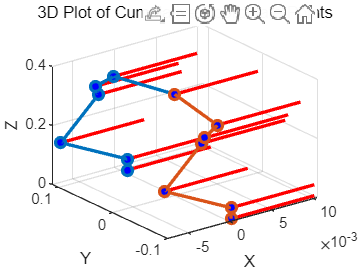

% 定义六个相对坐标点
relative_coords2 = [
    % -0.00110,  0.095,   -0.013327; % left_hip_pitch
    %  0.00185,  0.0055,  -0.024;    % left_hip_roll
    %  0,       -0.0055, -0.02315;  % left_hip_yaw
    % -0.0045,  -0.0000, -0.128;    % left_knee_jo
    %  0.008,    0,       -0.118;    % left_foot_y_jo
    %  0,        0.001,   -0.037;    % left_foot_x_jo
     0      ,0      ,           0.343477;
     
    %  0.00110, -0.095,   -0.013327; % right_hip_pitch 
    % -0.00185,  -0.0055,   -0.024;    % right_hip_roll
    %  0         ,0.0055,  -0.02315;  % right_hip_yaw
    % -0.0045,   -0.0000,  -0.128;    % right_knee_jo
    %  0.008,     0,        -0.118;    % right_foot_y_jo
    %  0,         -0.001,    -0.037;    % right_foot_x_jo
    -0.00110, -0.095,   -0.013327; % right_hip_pitch 
    -0.00185,  -0.0055,   -0.024;    % right_hip_roll
     0         ,0.0055,  -0.02315;  % right_hip_yaw
    -0.0045,   0.0000,  -0.128;    % right_knee_jo
     0.008,     0,        -0.118;    % right_foot_y_jo
     0,         0,    -0.037;    % right_foot_x_jo

];

% 初始化绝对坐标数组
absolute_coords2 = zeros(size(relative_coords2));

% 第一个点的绝对坐标与相对坐标相同
absolute_coords2(1, :) = relative_coords2(1, :);

% 计算后续点的绝对坐标
for i = 2:size(relative_coords2, 1)
    absolute_coords2(i, :) = absolute_coords2(i-1, :) + relative_coords2(i, :);
end

% 提取X、Y、Z坐标
x2 = absolute_coords2(:,1);
y2 = absolute_coords2(:,2);
z2 = absolute_coords2(:,3);

% 绘制3D散点图并连接线段
hold on 
plot3(x2, y2, z2, '-o', 'MarkerFaceColor', 'blue', 'LineWidth', 2);


scale = 0.01; % 坐标系轴的长度
for i = 1:length(x)
    % 绘制X轴
    plot3([x2(i), x2(i) + scale], [y2(i), y2(i)], [z2(i), z2(i)], 'r', 'LineWidth', 2);
    % 绘制Y轴
    plot3([x2(i), x2(i)], [y2(i), y2(i) + scale], [z2(i), z2(i)], 'g', 'LineWidth', 2);
    % 绘制Z轴
    plot3([x2(i), x2(i)], [y2(i), y2(i)], [z2(i), z2(i) + scale], 'b', 'LineWidth', 2);
end



% figure 
% H=ones(8501, 1) * Hwalk-0.05;
% plot3(gait(:,2)+ (-0.00110)+( -0.00185),gait(:,3)+(-0.095)+(-0.0055),H+(-0.013327)+( -0.024));
% hold on 
% plot3(gait(:,4),gait(:,5),gait(:,6));
% hold on 
% plot3(gait(:,11),gait(:,12),gait(:,13));